# Lista 2 - Parte 04

Autor: Francisco Castro

Data: 23/11/2019

## Introdução

    Este documento refere-se à resolução da 4ª parte da lista computacional 02 da disciplina EES-60, ministrada pelo prof. Dr. Jacques Waldmann em 2019, cujo objetivo é performar análise da covariância verdadeira na implementação ingênua do filtro de Kalman que desconsidere análise de observabilidade ao problema de rastreio 1D de MRU quando há erro de bias no sensor de posição e o efeito sobre o viés no erro de estimação do filtro.

## Metodologia

    As implementações foram feitas considerando a teoria exposta no material do curso, tanto para propagação da covariância do filtro como análise da covariância verdadeira. O código está exibido na seção Apêndice, no final deste documento. A análise de observabilidade foi feita baseando-se nos exercícios da parte 2 da lista 2, bem como nas implementações da parte 3 desta mesma lista. Contudo, os resultados anteriores não estão expostos neste documento.

    As análises foram feitas considerando os valores de segundo momento e desvio padrões, i.e. raiz quadrada das variância, dos estados do filtro que, por sua vez, associam-se às componentes observáveis. No caso 1, considera como primeira componente observável apenas a posição e, portanto, a segunda acaba sendo a velocidade, obtida por derivação. No caso 2, considera-se o bias do sensor de posição na conta, resultando como primeira componente observável a posição adicionada do bias, modelado como constante aleatória (*random constant*), mas que gera, analogamente, a velocidade para a segunda componente observável.

    As variâncias propagadas e atualizadas pelo filtro foram obtidas da diagonal principal das matrizes P_priori e P_posteriori. Os segundos momentos propagados e atuallizados foram extraídos da diagonal principal do bloco 2x2 inferior direito das matrizes C_priori e C_posteriori, respectivamente.

## Resultados

**Caso 1: Implementação ingênua**

    Neste momento consideraremos uma implementação do filtro de Kalman que desconsidera o bias no sensor de posição. 

T = [ ...
    1 0 0; ...
    0 1 0 ...
    ];

O que nos dá

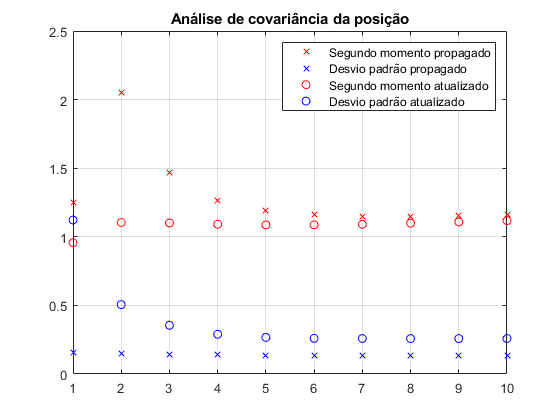

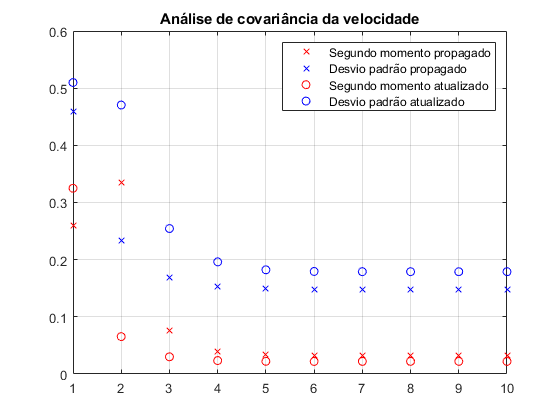

trueCovAnalysis(T, 10, 1);

**Caso 2: Implementação sagaz**

    Agora, com um pouco mais de experiência e maturidade em implementações de filtros de Kalman e análise de observabilidade, consideraremos uma implementação que considera o bias no sensor de posição. Desta forma, a transformação linear que leva do estado de projeto para o estado verdadeiro T passa a ser a descrita abaixo.

T = [ ...
    1 0 1; ...
    0 1 0 ...
    ];

Portanto

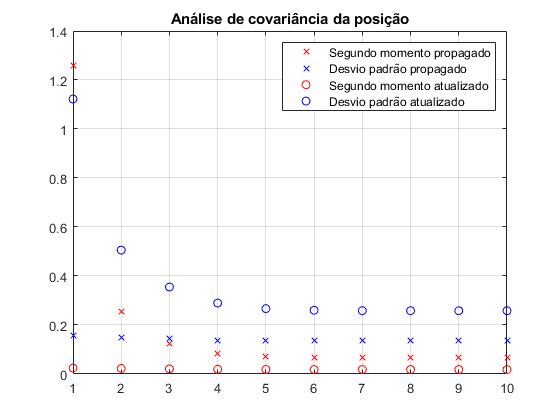

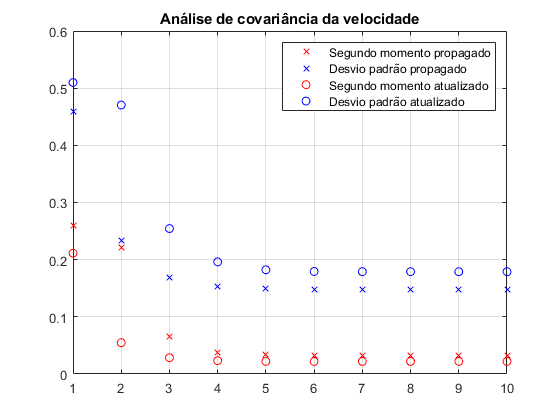

trueCovAnalysis(T, 10, 1);

**Variação do caso 1**

    Retornando para a matriz T que representa a implementação ingênua (caso 1)

T = [ ...
    1 0 0; ...
    0 1 0 ...
    ];

Temos a repetição da análise alterando a covariância q2 para 10.q2  nas equações de propagação da covariância do filtro. Tal mudança provoca um efeito de aumento na incerteza no modelo de constante aleatória no filtro de Kalman. Com isso

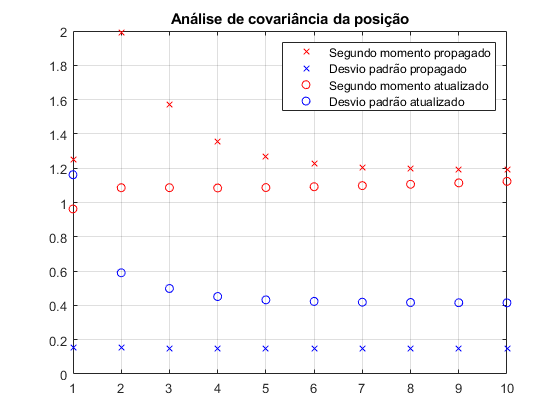

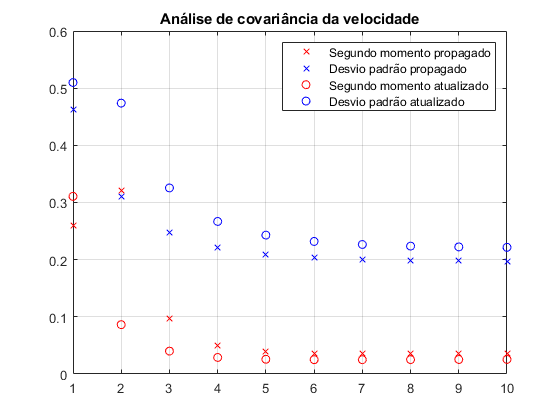

trueCovAnalysis(T, 10, 10);

## Análises

    Primeiramente, nota-se que a análise da covariância do desvio padrão para velocidade não altera-se do primeiro para o segundo caso, uma vez que, sendo o bias uma constante, a derivada da primeira componente observável anulará o efeito deste, sendo ela constituída por posição corrompida por bias ou não. Portanto, mesmo quando pensa-se não estar considerando o efeito de bias no sensor de posição, o filtro deve funcionar para a estimação da velocidade, o que pode ser confirmado, também, pela análise do segundo momento (pontos vermelhos) na estimação da velocidade, que nos indica estimativas não inviesadas para esta em ambos os casos.

    Por outro lado, a análise do segundo momento para a posição mostra, no caso 1, um claro inviesamento na estimativa, ao passo que, no caso 2, com a correção das componentes observáveis o segundo momento tende a zero, indicando uma estimativa não (ou menos) inviesada.

    Por fim, o aumento da incerteza do bias no modelamento impacta mais nas soluções de covariância do que nos cálculos de segundo momento. O filtro tem, neste caso, mais incerteza na estimativa que está fazendo (considera menos as estimativas e mais as medidas), conformando-se como um filtro de "baixa autoestima".

    Dessa forma, as medidas de covariância atualizada estarão maiores e, portanto, apresentarão um gap com relação aos valores de covariância propagada que é tão maior quando maior for o fator multiplicativo da covariância da incerteza do modelo inputado. Ao decorrer da mudança, os valores de segundo momento propagados para a posição parecem aumentar, ao passo que os atualizados mantém-se consistentes. Já quanto ao segundo momento associado à estimação de velocidade, este indica uma estimava cada vez menos inviesada quanto maior a incerteza q2 considerada.

## Apêndice

function trueCovAnalysis(T, k, multiFactor)

%% Descrição do sistema discretizado

Ts = 1; % [s]

% Modelo verdadeiro
F = [ ...
    1 Ts 0; ...
    0 1 0; ...
    0 0 1 ...
    ];
H = [ 1 0 1 ];

q1 = 0.1^2; % Covariância do ruído de velocidade [m^2/s^2/Hz]
q2 = 0.1^2; % Covariância da incerteza do bias [m^2/Hz]

Qd = [ ...
    0 0 0; ...
    0 q1 0; ...
    0 0 q2 ...
    ]*Ts;
R = 0.025; % [m^2]

% Modelo de projeto (filtro)
F_linha = [ ...
    1 1; ...
    0 1 ...
    ];
H_linha = [ 1 0 ];
Qd_linha = [ ...
    q2*multiFactor 0; ...
    0 q1 ...
    ]*Ts;


%% Condições iniciais
P_posteriori_linha = [ ...
    1 0; ...
    0 0.25 ...
    ];

C_posteriori = [ ...
    0 0 0 0 0; ...
    0 0.25 0 0 0.25; ...
    0 0 1 1 0; ...
    0 0 1 1 0; ...
    0 0.25 0 0 0.25 ...
    ];


for i = 1:k
%% Equações da covariância computada pelo filtro
n = size(T,1);
% Obtemos P-_n a partir de P+_n-1
P_priori_linha = F_linha*P_posteriori_linha*F_linha'+Qd_linha;

% Obtemos K_n a partir de P-_n
K_linha = P_priori_linha*H_linha'/(H_linha*P_priori_linha*H_linha'+R);

% Obtemos P+_n a partir de P-_n
P_posteriori_linha = (eye(n)-K_linha*H_linha)*P_priori_linha;


%% Análise da covariância verdadeira 
n = size(T,2);

% Passo 1
DeltaF = T*F - F_linha*T;

% Passo 2
Fc = [F, zeros(length(DeltaF),length(F_linha)); DeltaF, F_linha];
Phic = Fc;

% Passo 3
Qc = [eye(n); T]*Qd*[eye(n), T'];

% Passo 4
DeltaH = H - H_linha*T;

% Passo 5
B = [...
    eye(n), zeros(n, length(K_linha*H_linha)); ...
    -K_linha*DeltaH, eye(length(K_linha*H_linha)) - K_linha*H_linha ...
    ];

% Passo 6
Kc = [ ...
    zeros(n,size(K_linha,2)); ...
    -K_linha ...
    ];

% Passo 7
C_priori = Phic*C_posteriori*Phic'+Qc;

% Passo 8
C_posteriori = B*C_priori*B' + Kc*R*Kc';

%% Coleta de resultados
% Propagada
resultados(1,i) = C_priori(4,4);
resultados(2,i) = C_priori(5,5);
resultados(3,i) = sqrt(P_posteriori_linha(1,1));
resultados(4,i) = sqrt(P_posteriori_linha(2,2));

% Atualizada
resultados(5,i) = C_posteriori(4,4);
resultados(6,i) = C_posteriori(5,5);
resultados(7,i) = sqrt(P_priori_linha(1,1));
resultados(8,i) = sqrt(P_priori_linha(2,2));
end

%% Plots
figure;
plot(resultados(1,:)', 'rx')
hold on
plot(resultados(3,:)', 'bx')
plot(resultados(5,:)', 'ro')
plot(resultados(7,:)', 'bo')
legend( ...
    'Segundo momento propagado', ...
    'Desvio padrão propagado', ...
    'Segundo momento atualizado', ...
    'Desvio padrão atualizado' ...
    );
title('Análise de covariância da posição');
grid on

figure;
plot(resultados(2,:)', 'rx')
hold on
plot(resultados(4,:)', 'bx')
plot(resultados(6,:)', 'ro')
plot(resultados(8,:)', 'bo')
legend( ...
    'Segundo momento propagado', ...
    'Desvio padrão propagado', ...
    'Segundo momento atualizado', ...
    'Desvio padrão atualizado' ...
    );
title('Análise de covariância da velocidade');
grid on

end